
8793

ans = 8793

IAE = 57.1977				P = 97.3259		I = 45.4146		D = 0.77487
IAE = 45.0967				P = 69.6707		I = 104.2413		D = 0.53655
IAE = 623.6643				P = 103.6253		I = 41.1859		D = 2.3399
IAE = 25.5634				P = 20.1491		I = 124.9533		D = 1.549
IAE = 24.1647				P = 26.5028		I = 48.4892		D = 1.494
IAE = 71.0872				P = 98.0689		I = 11.9621		D = 0.47207
IAE = 881.3292				P = 38.7468		I = 2.7906		D = 3.9414
IAE = 34.093				P = 64.1617		I = 67.7907		D = 1.7503
IAE = 890.2725				P = 81.0262		I = 12.4932		D = 3.0857
IAE = 54.9697				P = 54.8782		I = 117.1071		D = 3.0066
IAE = 28.3155				P = 25.5886		I = 92.6442		D = 3.478
IAE = 53.8409				P = 9.6764		I = 58.6802		D = 3.2566
IAE = 27.9744				P = 14.797		I = 34.7465		D = 2.1343
IAE = 30.1679				P = 56.6808		I = 106.4313		D = 1.0991
IAE = 837.0435				P = 50.371		I = 7.4405		D = 3.5439
IAE = 36.7108				P = 32.9886		I = 71.1267		D = 3.4068
IAE = 86.928				P = 82.5334		I = 76.1736		D = 0.18104
IAE = 65.8978				P = 83.2155		I = 39.3657		D = 0.33415
IAE = 229.6132				P = 80

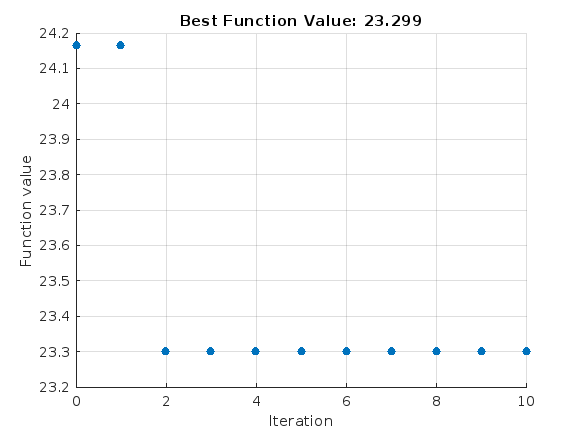

% Set nondefault solver options
options = optimoptions("particleswarm","InertiaRange",Inertia_range,...
    "SelfAdjustmentWeight",2.8,"SocialAdjustmentWeight",1.3,"MaxIterations",...
    10,"MaxStallIterations",10,"Display","iter","PlotFcn","pswplotbestf");

% Solve
[sol,obj] = particleswarm(@tunning,numvar,lower_bounds,...
    upper_bounds,options);


% Clear variables
clearvars options